## 3. gyakorlat

#### 1. Feladat

a) Írjuk fel az $A=\left[\begin{array}{cc}
2 & 3 \\
-1 & 6
\end{array}\right]$ mátrix karakterisztikus polinomját LER-rel, az $x_1=0, ~x_2=1$ pontokban számolt determinánsokból!

b) Írjuk fel a karakterisztikus polinom Frobenius-mátrix alakját, és ellenőrizzük a helyességét!

% Ellenőrzés

A=[2,3; -1,6];

D=[1,0; 1,1]

D =      1     0
     1     1


d=[15; 7]

d =     15
     7


D\d

ans =     15
    -8


#### 2. Feladat

a) Írjuk fel az $A=\left[\begin{array}{ccc}
1 & 0 & 0 \\
4 & 4 & 4\\
0 & 0 & 1
\end{array}\right]$ mátrix karakterisztikus polinomját LER-rel, az $x_1=-1, ~x_2=0, ~ x_3=2$ pontokban számolt determinánsokból!

b) Írjuk fel a karakterisztikus polinom Frobenius-mátrix alakját, és ellenőrizzük a helyességét!

% Ellenőrzés

A=[1,0,0; 4,4,4; 0,0,1];

B=[1,-1,1; 1,0,0; 1,2,4]

B =      1    -1     1
     1     0     0
     1     2     4


b=[-19;-4;-10]

b =    -19
    -4
   -10


q=B\b

q =     -4
     9
    -6


p=[1,fliplr(q')]

p =      1    -6     9    -4


x=linspace(0,5,100);
y=polyval(p,x)

y =    -4.0000   -3.5606   -3.1511   -2.7706   -2.4184   -2.0938   -1.7959   -1.5239   -1.2772   -1.0548   -0.8562   -0.6804   -0.5267   -0.3943   -0.2826   -0.1906   -0.1176   -0.0628   -0.0255   -0.0050   -0.0003   -0.0108   -0.0357   -0.0741   -0.1254   -0.1888   -0.2635   -0.3486   -0.4435   -0.5474   -0.6594   -0.7789   -0.9050   -1.0370   -1.1741   -1.3156   -1.4606   -1.6083   -1.7581   -1.9091   -2.0606   -2.2118   -2.3619   -2.5101   -2.6557   -2.7979   -2.9359   -3.0690   -3.1964   -3.3172


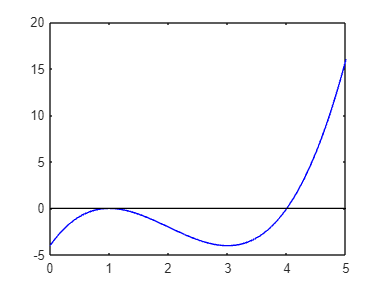

plot(x,y,'b-', x,x*0,'k')

eig(A)

ans =      4
     1
     1


#### 3. Feladat

Számítsuk ki az 1. és 2. feladatok megoldását a trace-módszerrel!

#### 4. Feladat

Készítsünk szimmetrikus illetve nem szimmetrikus teszt példákat a következő sajátérték feladatokhoz!

% Megoldás


#### 5. Feladat

Készítsünk programot a ,,trace-módszerre''!

-  Bemenő paraméter: `A` négyzetes mátrix;

- Kimenő paraméter: `p`, az `A` mátrix karakterisztikus polinomja.

% Megoldás

A=[1,0,0; 4,4,4; 0,0,1];

p=trace_modszer(A)

p =      1    -6     9    -4
